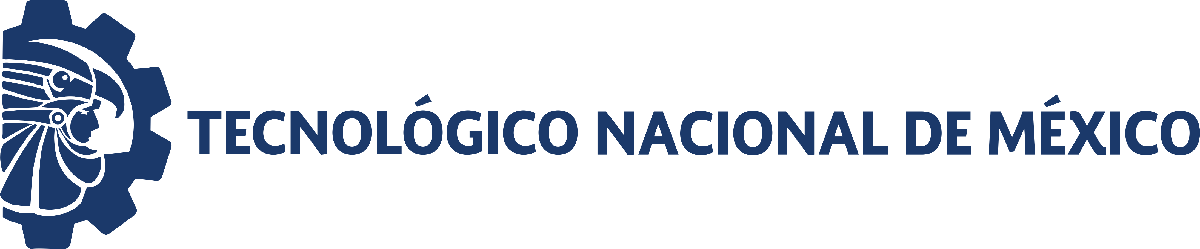                                 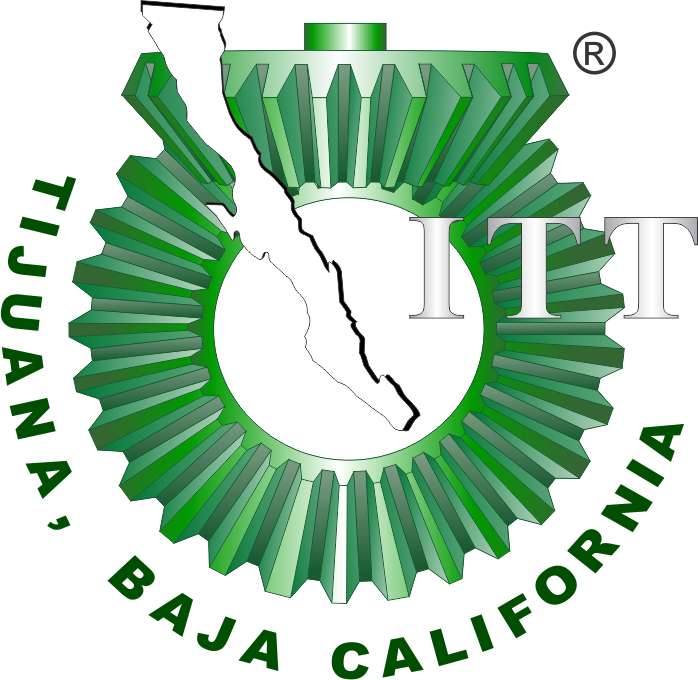

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

# Práctica 1: Sistema presa-depredador de Lotka-Volterra

**Objetivo. ** Aplicar el sistema de Lotka-Volterra para analizar los datos registrados en la interacción de dos especies articas, liebres (presa) y linces (depredador) durante 20 años. El sistema presa-depredador se formula mediante las siguientes dos EDOs de primer orden:


$$\dot x = \alpha x - \beta xy
$$



$$\dot y = \delta xy - \gamma y$$


donde los valores de los parámetros $\alpha$,$\beta ,$$\delta ,$$\gamma >0$, y las condiciones iniciales $x\left(0\right),$$y\left(0\right)>0$.

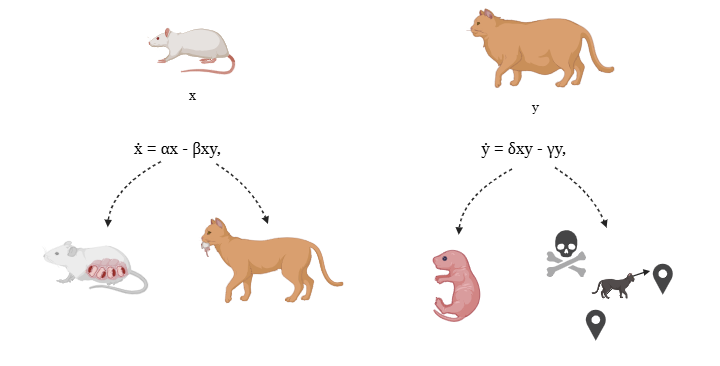

## Referencias

[1] Valle, Paul A., Syllabus para Biología de Sistemas y Gemelos Digitales, Tecnológico Nacional de México / Instituto Tecnológico de Tijuana, Tijuana, B.C., México, 2026. Permalink: [https://biomath.xyz/course/](https://biomath.xyz/course/) 

[2] Garfinkel, Alan, Jane Shevtsov, and Yina Guo. Modeling life: the mathematics of biological systems. Springer International Publishing AG, 2017.

## Información general

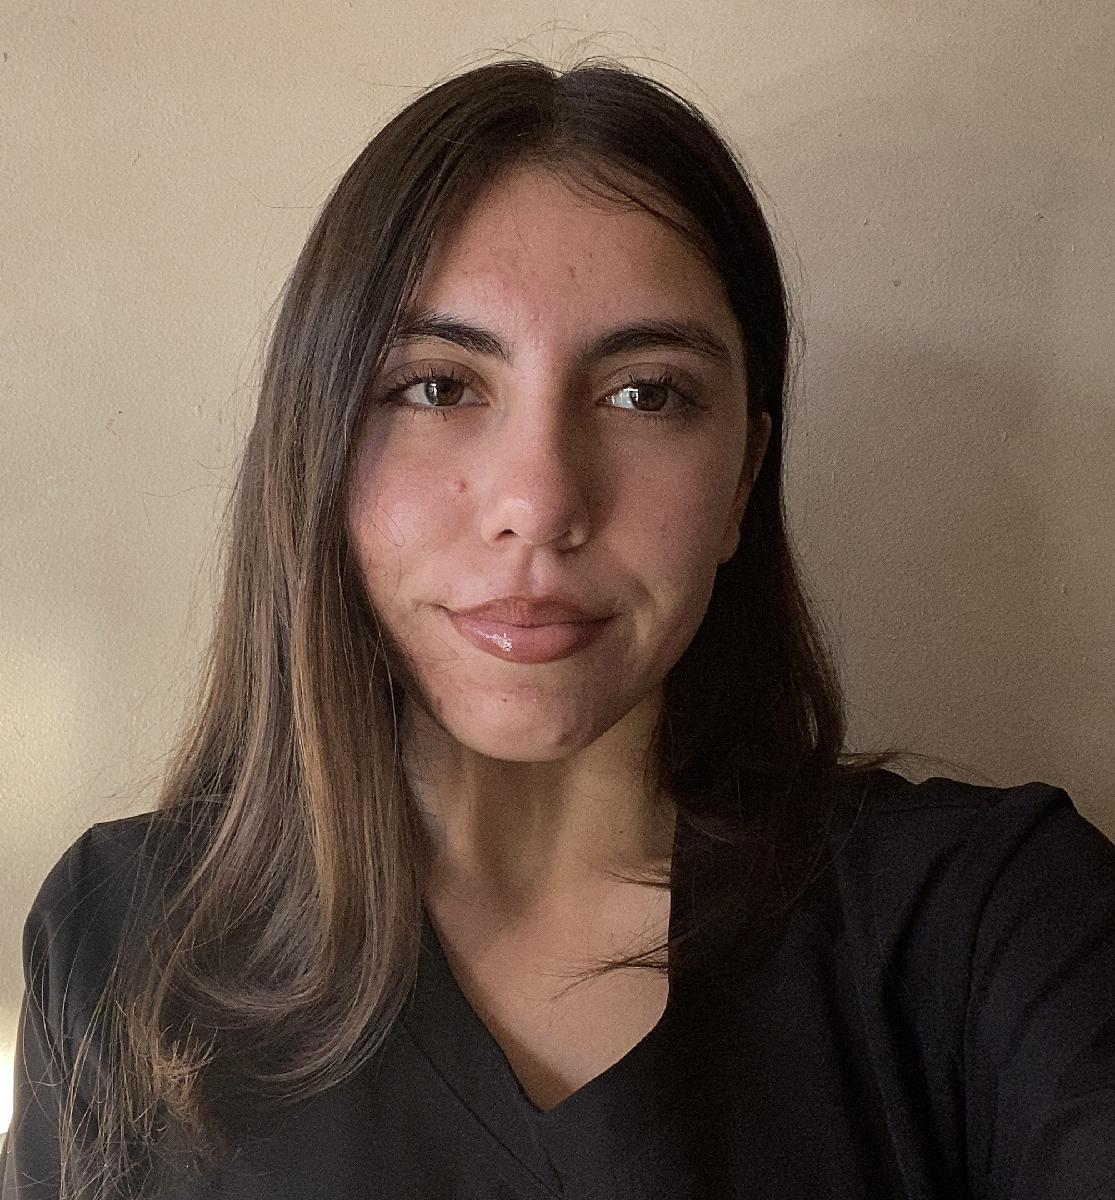

Nombre del alumno: **Lopez Pardo Brianna Vanessa**

Número de control: **22212261**

Correo institucional: **L22212261@tectijuana.edu.mx**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

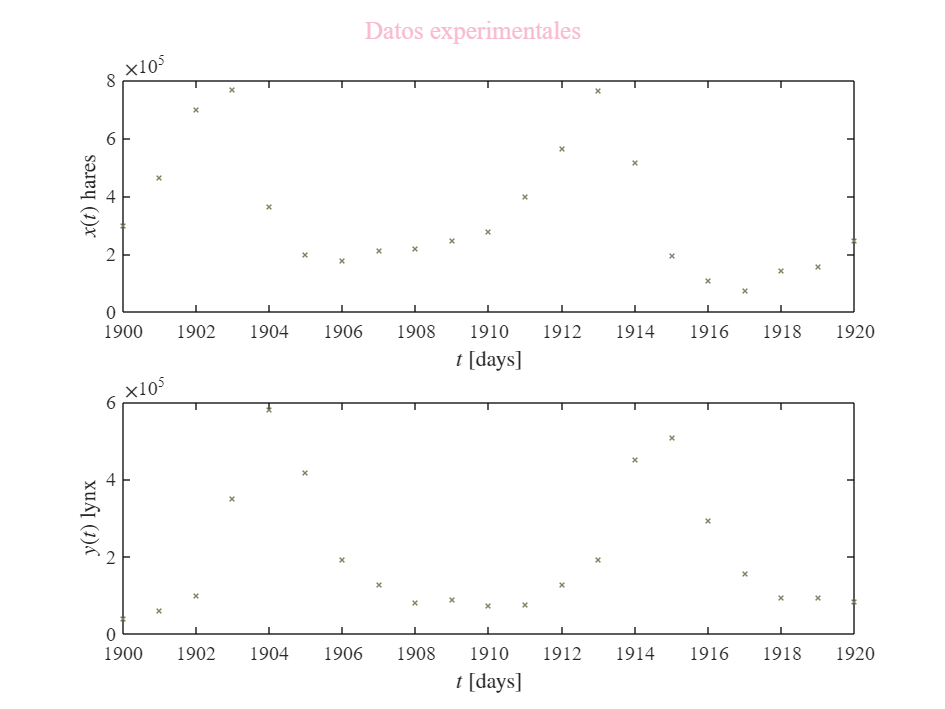

clc; clear; close all; warning('off','all')
smooth= false; normalize= false;
[to,xo,yo] = getdata ('data.csv', smooth,normalize);
plotsys(to,xo,yo); sgtitle ('Datos experimentales','Color', '#F8BBD0', 'FontName', 'Times New Roman'); ... 
exportgraphics(gcf, 'data_raw.pdf', 'ContentType', 'vector')

## Procesamiento de datos

### Datos visualizados

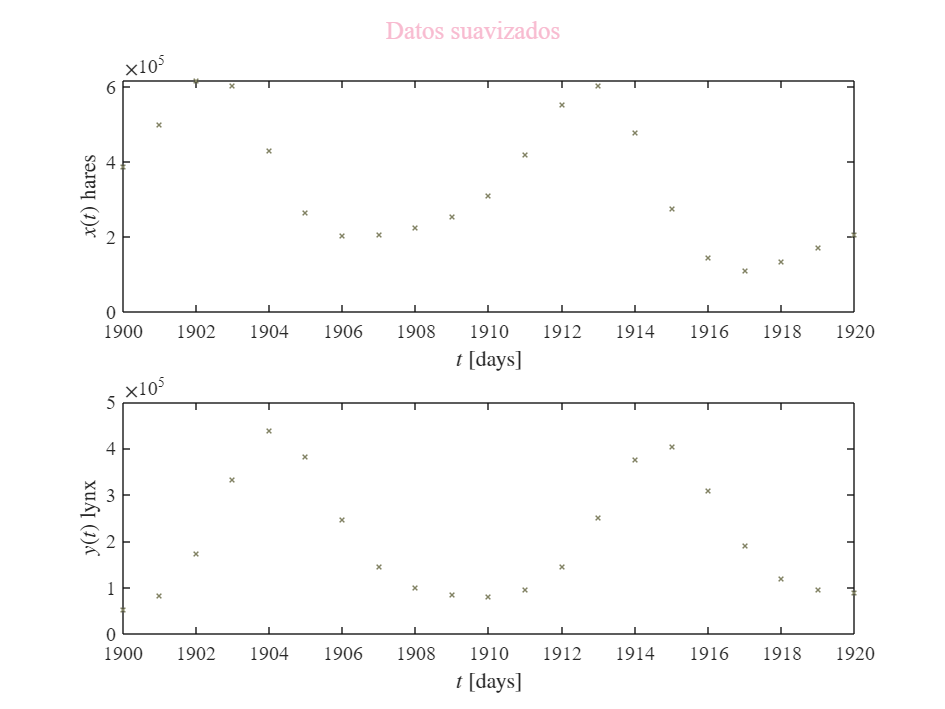

smooth = true; normalize = false;
[to,xo,yo]= getdata('data.csv', smooth, normalize);
plotsys(to,xo,yo); sgtitle ('Datos suavizados','Color', '#F8BBD0', 'FontName', 'Times New Roman'); ...
exportgraphics (gcf, 'data_smooth.pdf', 'ContentType', 'vector' )

### Datos normalizados

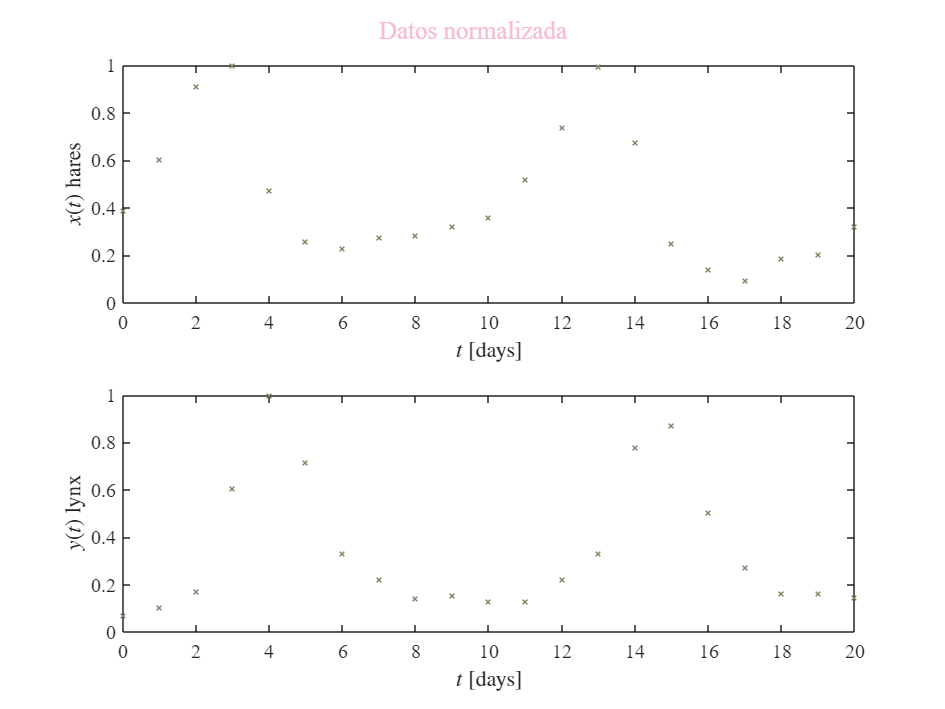

smooth = false; normalize = true;
[to,xo,yo]= getdata('data.csv', smooth, normalize);
plotsys(to,xo,yo); sgtitle ('Datos normalizada','Color', '#F8BBD0', 'FontName', 'Times New Roman'); ...
exportgraphics (gcf, 'data_normalized.pdf', 'ContentType', 'vector' )

### Datos normalizados y suavizados

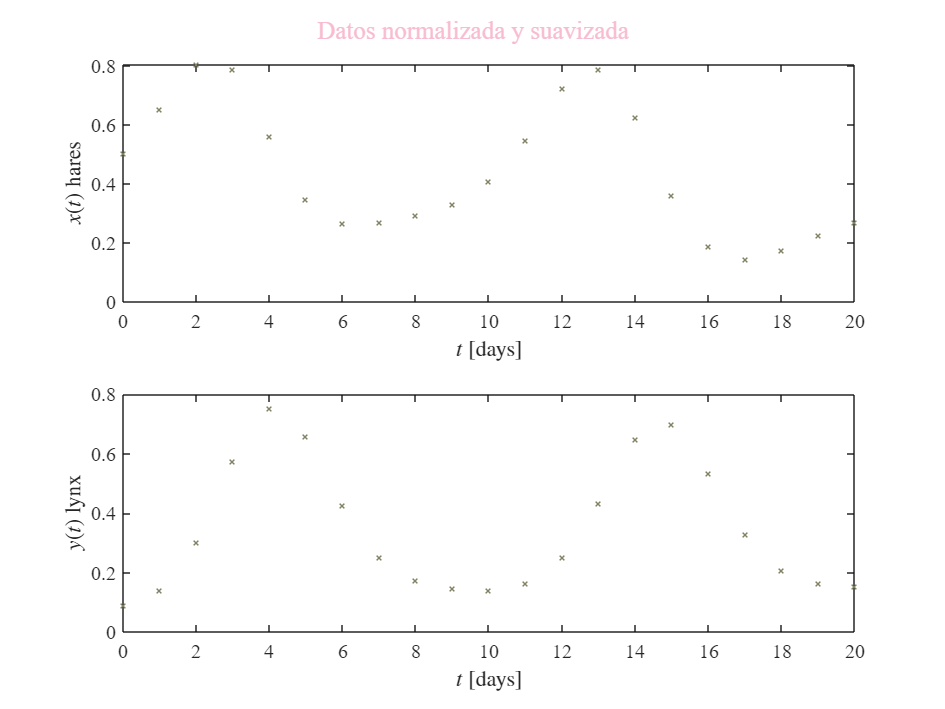

smooth = true; normalize = true;
[to,xo,yo]= getdata('data.csv', smooth, normalize);
plotsys(to,xo,yo); sgtitle ('Datos normalizada y suavizada','Color', '#F8BBD0', 'FontName', 'Times New Roman'); ...
exportgraphics (gcf, 'data_smooth_normalized.pdf', 'ContentType', 'vector' )

## Regresión no lineal

clear; close all
smooth = false; normalize = true;
[to,xo,yo] = getdata('data.csv', smooth,normalize);
Po = [ 1;1 ;1; 1]; biostats = true; 
mdl = Variant(to,xo,yo,Po, biostats);

Degrees of freedom:38
t-students value :2.0244
Significance value (alpha):0.05
 
    Parameters     Estimate       SE         MoE              CI95             PValue  
    ___________    ________    ________    ________    __________________    __________

    {["alpha"]}    0.56321     0.024531    0.012118    0.51355    0.61287    7.0566e-24
    {["beta" ]}     1.6856     0.094106    0.046486     1.4951     1.8761    4.0282e-20
    {["delta"]}     2.0058     0.090559    0.044734     1.8225     2.1892    2.5184e-23
    {["gamma"]}    0.81344     0.036692    0.018125    0.73916    0.88772    2.4393e-23

R-cuadrada ordinaria:0.95291R-cuadrada ajustada:0.9492Suma residual de cuadrados:0.15285Criterio de informacion de Akaike:-108.6797Criterio de informacion de Akaike ajustado (n/k<40):-1

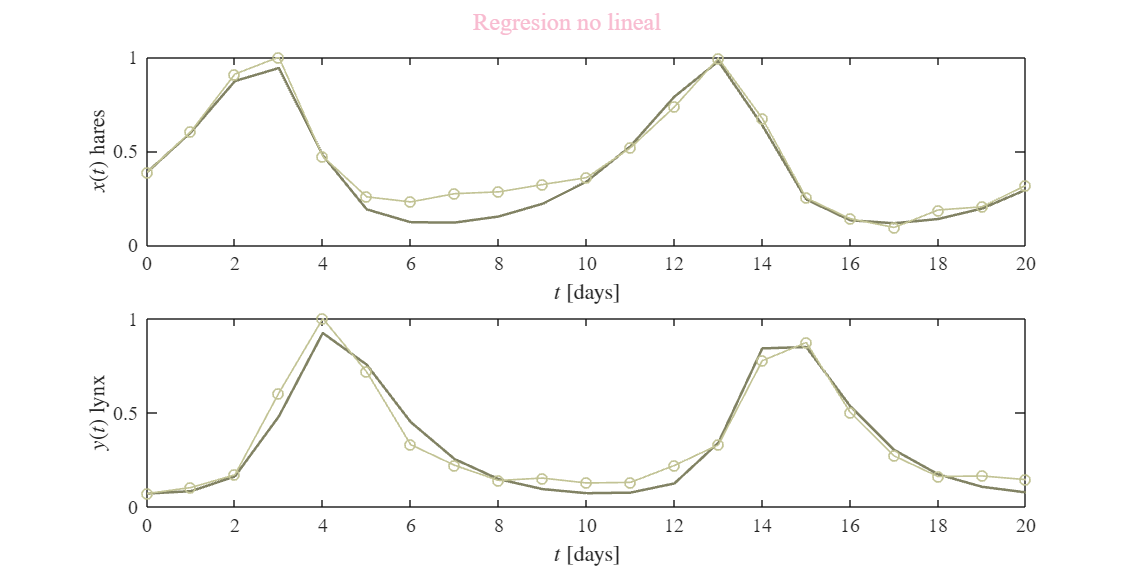

fa = mdl.Fitted;
fa = reshape(fa,[],2);
xa = fa(:,1); ya = fa(:,2);
plotresults(to,xo, yo, to, xa, ya); sgtitle ('Regresion no lineal','Color', '#F8BBD0', 'FontName', 'Times New Roman'); ... 
exportgraphics(gcf, 'data_nonlinear_regression.pdf', 'ContentType','vector')

## Predicción del modelo a 2t

clear; close all
smooth = false ; normalize = true;
[to,xo,yo ]= getdata('data.csv', smooth, normalize);
Po = [0.5,1.6,1.9,0.8]; biostats = false;
mdl = Variant(to,xo,yo,Po, biostats);
par = table2array(mdl.Coefficients(:,1));
alpha = par(1); beta = par(2); delta = par(3); gamma = par(4);
x0=xo(1);y0 = yo(1); tend = to(end); dt = 1E-3;

### Método de Heun

[th, xh,yh] = sysheun (x0,y0, alpha, beta, delta, gamma, 2*tend, dt)

th =          0
    0.0010
    0.0020
    0.0030
    0.0040
    0.0050
    0.0060
    0.0070
    0.0080
    0.0090


xh =     0.3879
    0.3881
    0.3883
    0.3885
    0.3886
    0.3888
    0.3890
    0.3892
    0.3893
    0.3895


yh =     0.0708
    0.0708
    0.0708
    0.0708
    0.0708
    0.0708
    0.0708
    0.0708
    0.0708
    0.0708


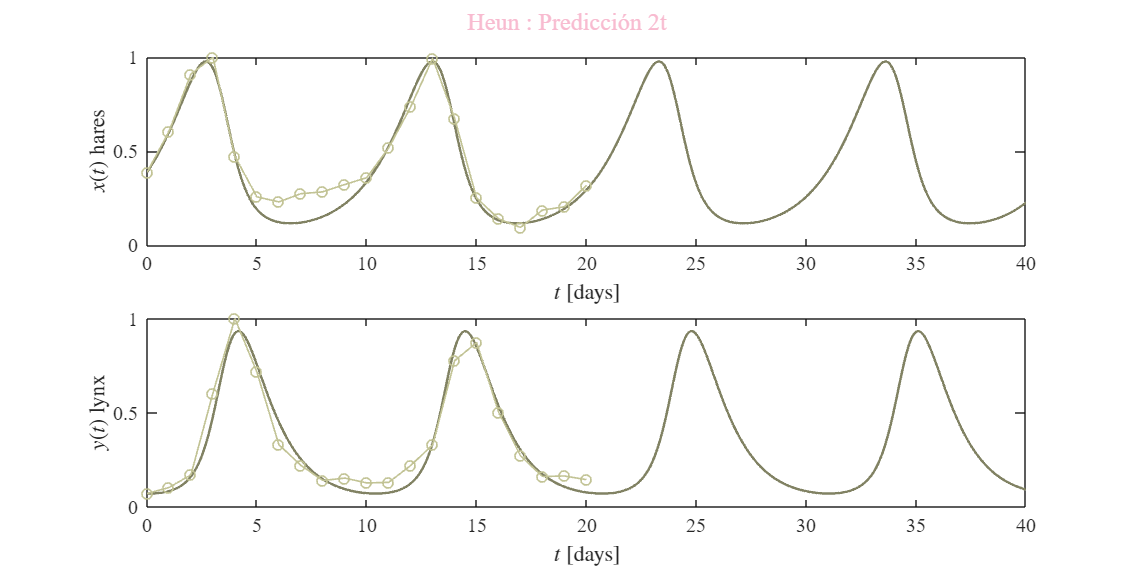

plotresults(to,xo,yo,th, xh,yh); sgtitle ('Heun : Predicción 2t','Color', '#F8BBD0', 'FontName', 'Times New Roman'); ...
exportgraphics(gcf, 'data_heun_prediction.pdf', 'ContentType','vector')

### Método de Euler

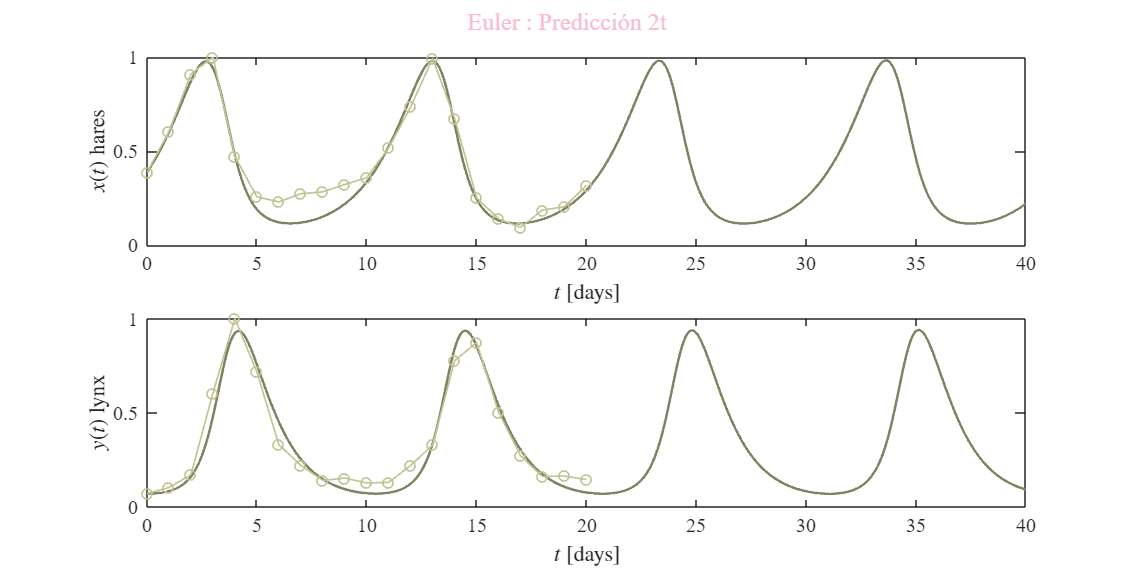

[te,xe,ye] = syseuler(x0,y0,alpha,beta,delta,gamma,2*tend,dt);
plotresults(to,xo,yo,te, xe,ye); sgtitle ('Euler : Predicción 2t','Color', '#F8BBD0', 'FontName', 'Times New Roman'); ...
exportgraphics(gcf, 'data_euler_prediction.pdf', 'ContentType','vector')

## Soluciones y trayectoria

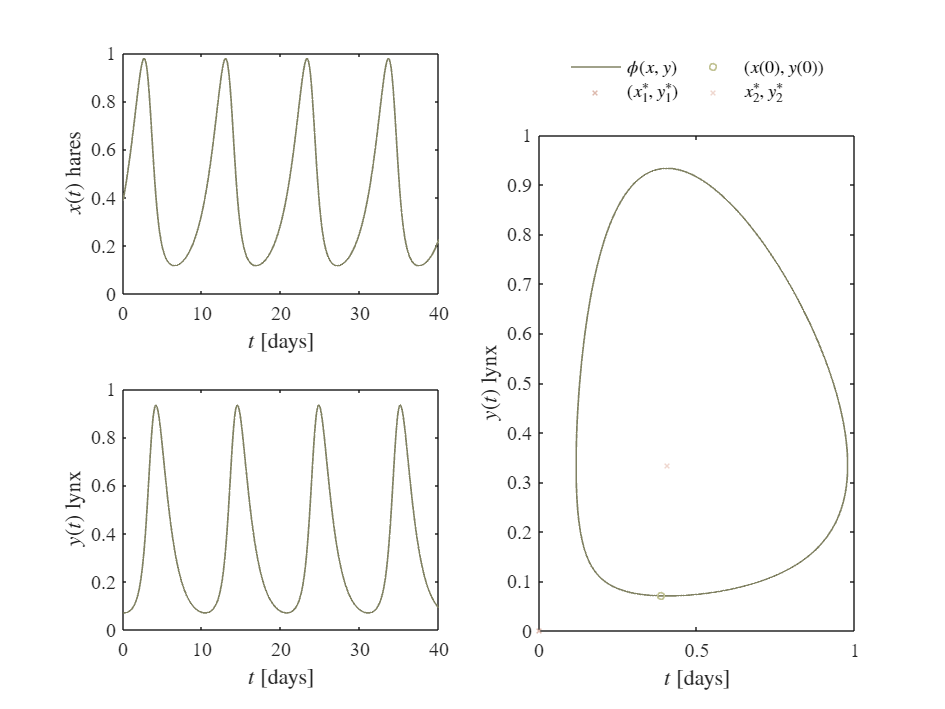

clear; close all
smooth = false; normalize = true;
[to,xo,yo]= getdata('data.csv', smooth,normalize);
Po = [0.5; 1.6; 1.9; 0.8]; biostats = false;
mdl = Variant(to,xo,yo,Po, biostats);
par =table2array(mdl.Coefficients(:,1));
alpha = par(1); beta = par(2); delta = par(3); gamma = par(4);
x0 = xo(1); y0=yo(1); tend= to(end); dt = 1E-3;
[th, xh, yh] = sysheun(x0,y0, alpha, beta,delta,gamma,2*tend,dt);
plotedos(th,xh,yh,par); exportgraphics(gcf,'phaseplane.pdf','ContentType','vector')

### Influencia de dt en la aproximacion de las soluciones: Euler

clear; close all
smooth = false ; normalize = true; 
[to,xo,yo]= getdata('data.csv', smooth,normalize);
Po= [0.5; 1.6; 1.9;0.8]; biostats = false;
mdl = Variant(to,xo,yo,Po,biostats);
par =table2array(mdl.Coefficients(:,1))

par =     0.5632
    1.6856
    2.0058
    0.8134


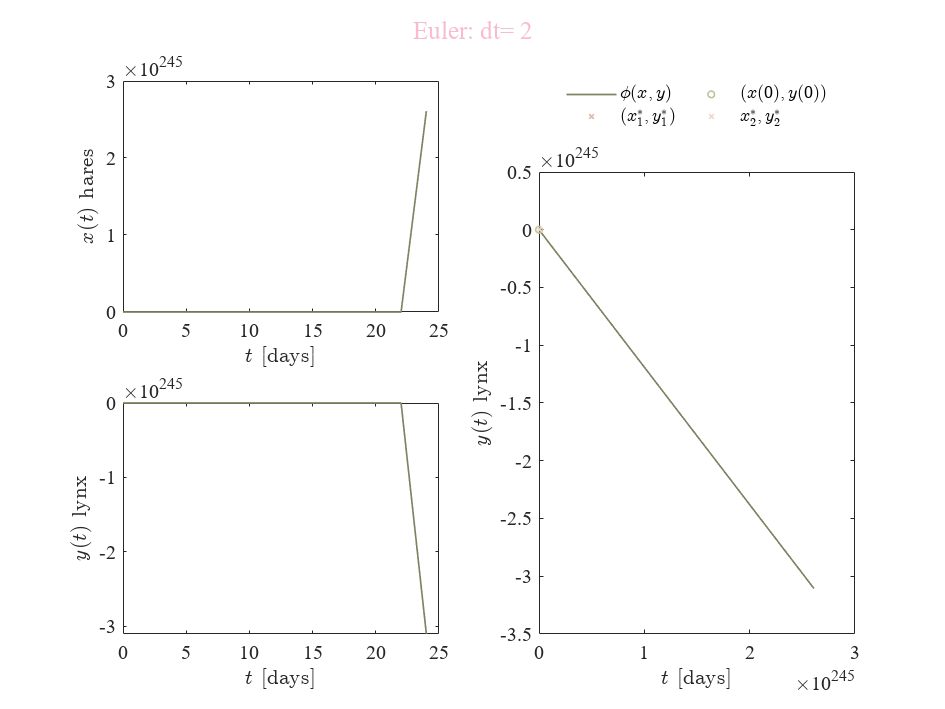

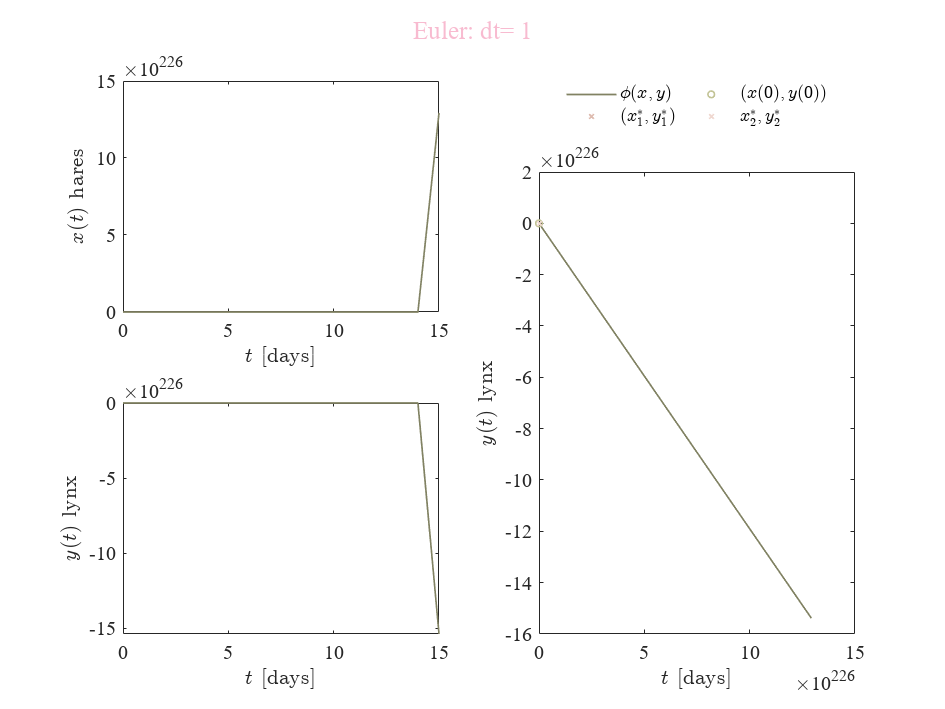

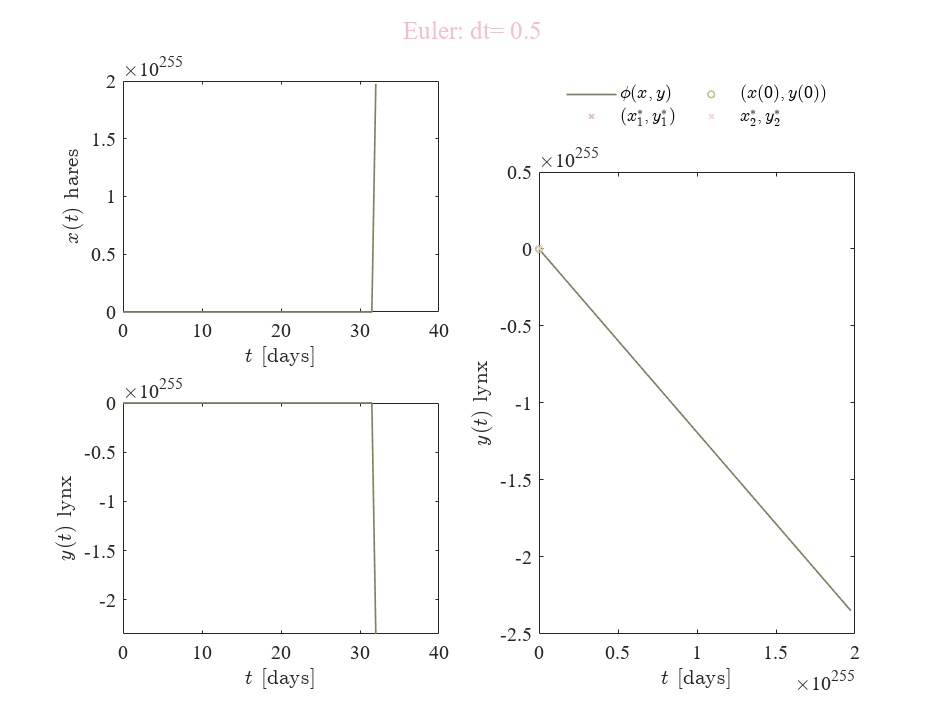

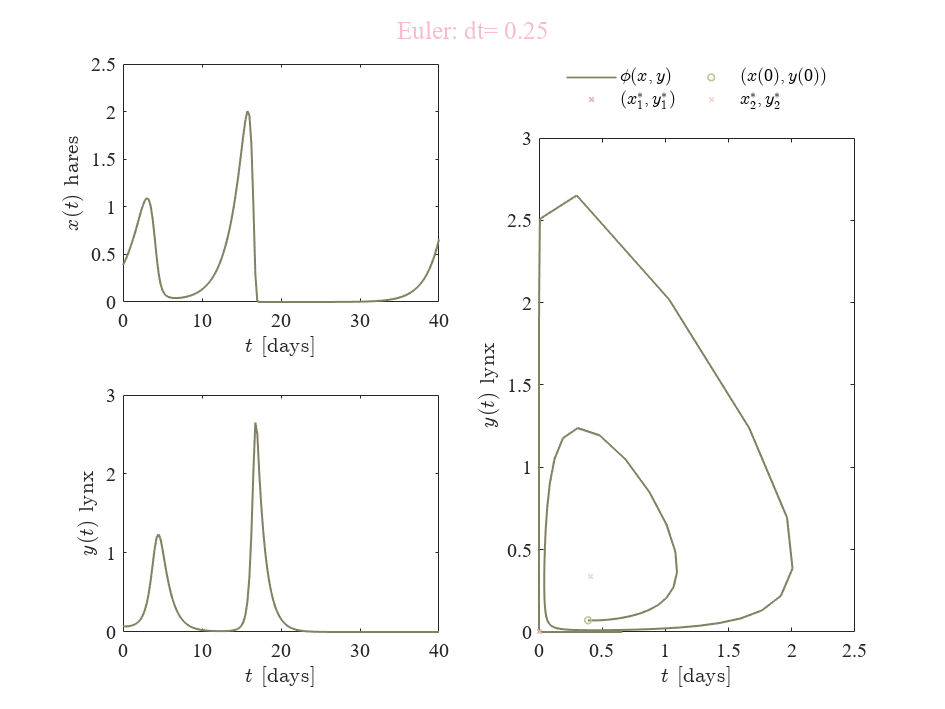

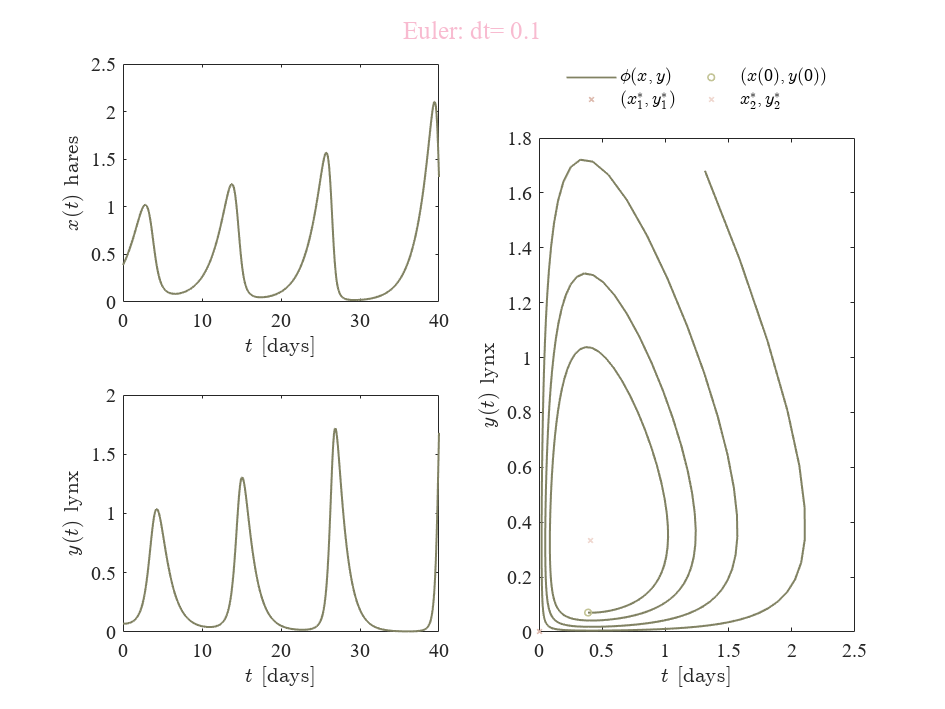

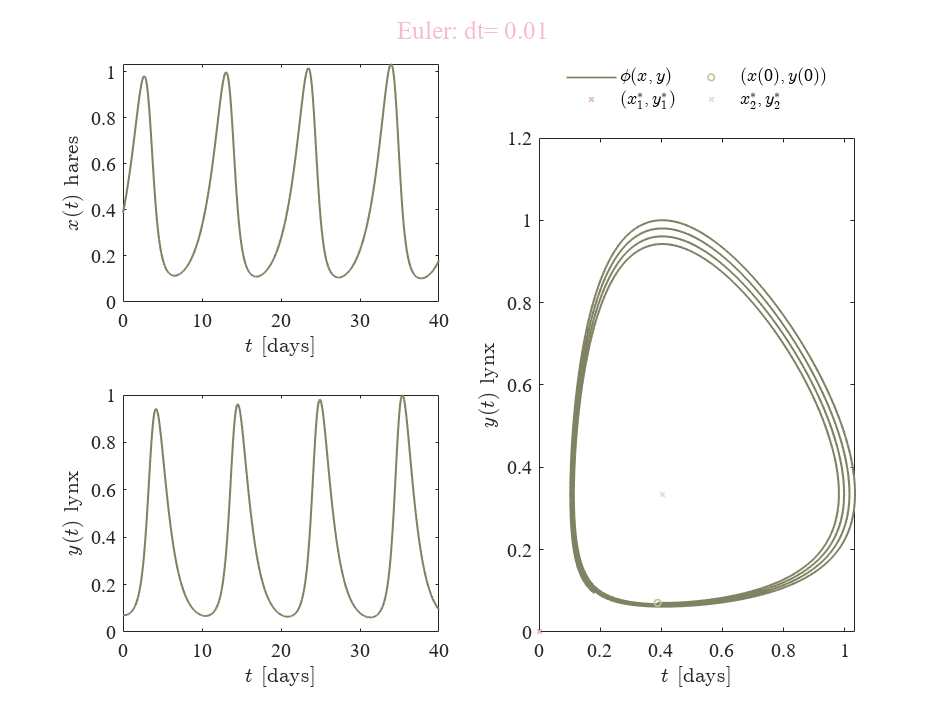

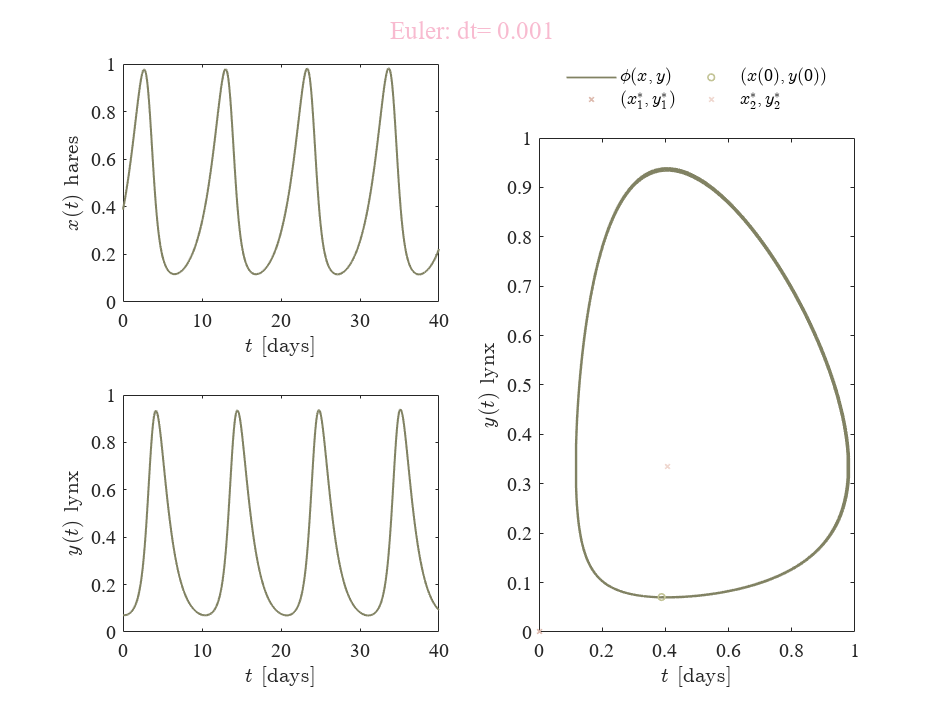

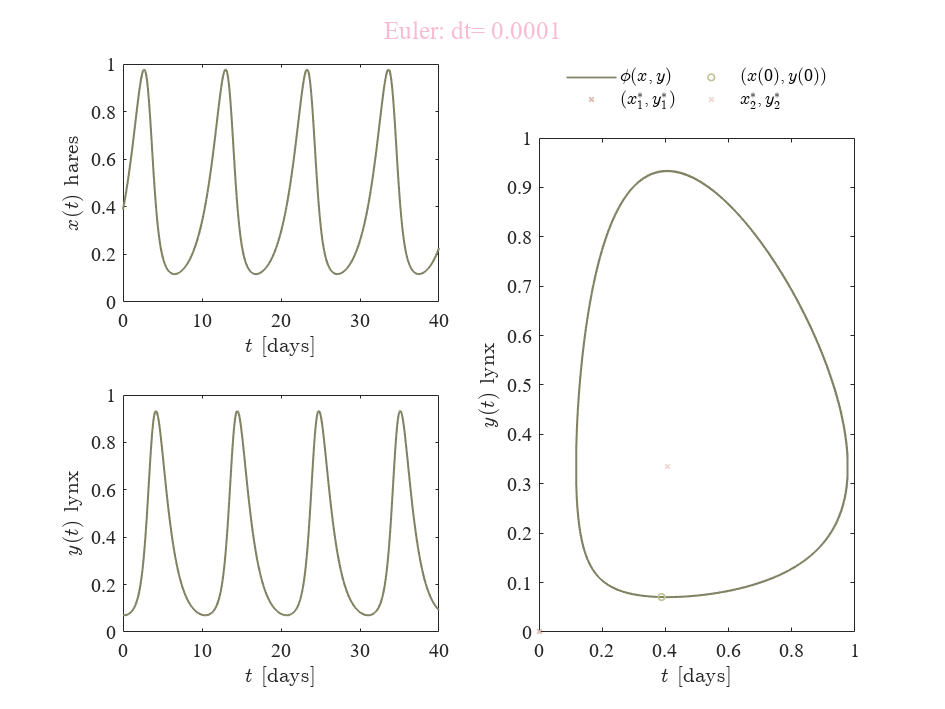

alpha = par(1); beta = par(2); delta = par(3); gamma = par(4);
x0 = xo(1); y0=yo(1); tend= to(end);
dt = [2;1;0.5;0.25;0.1;1E-2;1E-3;1E-4;1E-5;1E-6;1E-7];
for i = 1:length(dt)
     [te,xe,ye] = syseuler(x0,y0,alpha,beta,delta,gamma,2*tend,dt(i));
     plotedos(te,xe,ye,par); sgtitle(['Euler: dt= ',num2str(dt(i))], 'Color', '#F8BBD0', 'FontName', 'Times New Roman'); ...
         exportgraphics(gcf,['euler dt', num2str(dt(i)),'.pdf'],'ContentType','vector')
end

### Influencia de dt en la aproximacion de las soluciones: Heun

clear; close all
smooth = false ; normalize = true; 
[to,xo,yo]= getdata('data.csv', smooth,normalize);
Po= [0.5; 1.6; 1.9;0.8]; biostats = false;
mdl = Variant(to,xo,yo,Po,biostats);
par =table2array(mdl.Coefficients(:,1))
alpha = par(1); beta = par(2); delta = par(3); gamma = par(4);
x0 = xo(1); y0=yo(1); tend= to(end);
dt = [2;1;0.5;0.25;0.1;1E-2;1E-3;1E-4;1E-5;1E-6;1E-7];
for i = 1:length(dt)
     [th,xh,yh] = syseuler(x0,y0,alpha,beta,delta,gamma,2*tend,dt(i));
     plotedos(th,xh,yh,par); sgtitle('dt value= ',num2str(dt(i)), 'Color', '#F8BBD0', 'FontName', 'Times New Roman');...
         exportgraphics(gcf,['heun dt', num2str(dt(i)),'.pdf'],'ContentType','vector')
end

## Puntos de equilibrio

clc; clear
syms x y alpha beta delta gamma 
dx_dt = alpha*x-beta*x*y == 0;
dy_dt = delta*x*y-gamma*y == 0;

fxy = solve([dx_dt,dy_dt],[x,y]);
fprintf(['Puntos de equilibrio del sistema:', num2str(length(fxy.x))]); ...
fprintf(['Puntos de equilibrio del sistema:', num2str(length(fxy.y))]); 
xe_1 = fxy.x(1); ye_1 = fxy.y(1);
xe_2 = fxy.x(2); ye_2 = fxy.y(2);

fprintf('Puntos de equilibrio del simbolicos:');...
    disp([xe_1, ye_1; xe_2, ye_2])

## Soluciones y trayectorias positivamente invariantes

clear; close all
smooth = false ; normalize = true; 
[to,xo,yo]= getdata('data.csv', smooth,normalize);
Po= [0.5; 1.6; 1.9;0.8]; biostats = false;
mdl = Variant(to,xo,yo,Po,biostats);
par =table2array(mdl.Coefficients(:,1))
alpha = par(1); beta = par(2); delta = par(3); gamma = par(4);
tend = to(end); dt = 1E-3;
x0 = [xo(1),0, gamma/delta, 0.25,0.5,0.75,1,gamma/delta,0, alpha/beta, -0.1, -0.1, -0.1, 0.001,  0.001, 1,1 ];
y0 = [yo(1),0, alpha/beta, 0.25,0.5,0.75,1,0, alpha/beta,gamma/delta, 0.1, -0.1, -0.1, 0.001,  1, 0.001,1 ];
for i = 1:length(x0)
   [t,x,y] = sysheun(x0(i),y0(i),alpha,beta,delta,gamma,5*tend,dt);
    plotedos(t,x,y,par); sgtitle(['(x(0),y(0)) = (',num2str(x0(i)),',',num2str(y0(i)),')'],'Color', '#F8BBD0', 'FontName', 'Times New Roman');...
         exportgraphics(gcf,['initial_conditions', num2str((i)),'.pdf'],'ContentType','vector')
end

## Simulink

clear; close all
smooth = false ; normalize = true; 
[to,xo,yo]= getdata('data.csv', smooth,normalize);
Po= [0.5; 1.6; 1.9;0.8]; biostats = false;
mdl = Variant(to,xo,yo,Po,biostats);
par =table2array(mdl.Coefficients(:,1))
file = 'lotka_volterra';
sim (file);
parameters.StopTime = '100';

### odes para soluciones stiff

### Funcion de ode23s

parameters.Solver = 'ode23s';
f = sim (file, parameters);
plotedos(f.t,f.x,f.y,par); sgtitle('Simulink: ode23s ', 'Color', '#F8BBD0', 'FontName', 'Times New Roman');
exportgraphics(gcf, 'ode23s.pdf', 'ContentType','vector')

### Funcion de ode45

parameters.Solver = 'ode45';
f = sim (file, parameters); 
plotedos(f.t,f.x,f.y,par);  sgtitle('Simulink: ode23s', 'Color', '#F8BBD0', 'FontName', 'Times New Roman');
exportgraphics(gcf, 'ode45.pdf', 'ContentType','vector')

### Funcion de ode23tb

parameters.Solver = 'ode23tb';
parameters.MaxStep= '1E-1';
f = sim (file, parameters); 
plotedos(f.t,f.x,f.y,par); sgtitle('Simulink: ode23tb, FixedStep = 1E-1 ', 'Color', '#F8BBD0', 'FontName', 'Times New Roman');
exportgraphics(gcf, 'ode23tb.pdf', 'ContentType','vector')

### Funcion de ode23

parameters.Solver = 'ode23';
f = sim (file, parameters);
plotedos(f.t,f.x,f.y,par);  sgtitle('Simulink: ode23 ', 'Color', '#F8BBD0', 'FontName', 'Times New Roman'); 
exportgraphics(gcf, 'ode23.pdf', 'ContentType','vector')

### Funcion de ode113

parameters.Solver = 'ode113';
f = sim (file, parameters);
plotedos(f.t,f.x,f.y,par);  sgtitle('Simulink: ode113 ', 'Color', '#F8BBD0', 'FontName', 'Times New Roman'); 
exportgraphics(gcf, 'ode113.pdf', 'ContentType','vector')

### Funcion de ode23t

parameters.Solver = 'ode23t';
f = sim (file, parameters);
plotedos(f.t,f.x,f.y,par);  sgtitle('Simulink: ode23t ', 'Color', '#F8BBD0', 'FontName', 'Times New Roman');
exportgraphics(gcf, 'ode23t.pdf', 'ContentType','vector')

### Funcion de ode15s

parameters.Solver = 'ode15s';
parameters.MaxStep = '0.1';
f = sim (file, parameters);
plotedos(f.t,f.x,f.y,par);  sgtitle('Simulink: ode15s, FixedStep = 0.1', 'Color', '#F8BBD0', 'FontName', 'Times New Roman');  
exportgraphics(gcf, 'ode15s.pdf', 'ContentType','vector')

### ode para soluciones no stiff

### Funcion de ode1

parameters.Solver = 'ode1';
parameters.FixedStep = '0.01';
f = sim (file, parameters);
plotedos(f.t,f.x,f.y,par);  sgtitle('Simulink: ode1, FixedStep = 0.01 ', 'Color', '#F8BBD0', 'FontName', 'Times New Roman');
exportgraphics(gcf, 'ode1.pdf', 'ContentType','vector')

### Funcion de ode2

parameters.Solver = 'ode2';
parameters.FixedStep = '1E-1';
f = sim (file, parameters);
plotedos(f.t,f.x,f.y,par);  sgtitle('Simulink: ode2, FixedStep = 1E-1', 'Color', '#F8BBD0', 'FontName', 'Times New Roman');
exportgraphics(gcf, 'ode2.pdf', 'ContentType','vector')

### Funcion de ode3

parameters.Solver = 'ode3';
f = sim (file, parameters);
parameters.FixedStep = '1E-1';
plotedos(f.t,f.x,f.y,par);  sgtitle('Simulink: ode3, FixedStep = 1E-1 ', 'Color', '#F8BBD0', 'FontName', 'Times New Roman');
exportgraphics(gcf, 'ode3.pdf', 'ContentType','vector')

### Funcion de ode4

parameters.Solver = 'ode4';
f = sim (file, parameters);
parameters.FixedStep = '1E-1';
plotedos(f.t,f.x,f.y, par);  sgtitle('Simulink: ode4, FixedStep = 1E-1', 'Color', '#F8BBD0', 'FontName', 'Times New Roman');
exportgraphics(gcf, 'ode4.pdf', 'ContentType','vector')

### Funcion de ode5

parameters.Solver = 'ode5';
f = sim (file, parameters);
parameters.FixedStep = '1E-1';
plotedos(f.t,f.x,f.y,par);   sgtitle('Simulink: ode5, FixedStep = 1E-1', 'Color', '#F8BBD0', 'FontName', 'Times New Roman');
exportgraphics(gcf, 'ode5.pdf', 'ContentType','vector')

## Funcion ODE

clear; close all
smooth = false ; normalize = true; 
[to,xo,yo] = getdata ('data.csv', smooth,normalize);
Po= [0.5; 1.6; 1.9;0.8]; biostats = false;
mdl = Variant(to,xo,yo,Po,biostats);
par =table2array(mdl.Coefficients(:,1))
x0=xo(1); y0=yo(1);
% V(1) = x; V(2) = y;
[t, solV]= ode89(@(t,V)sysODE(V,par),[0,100],[x0,y0]);
x = solV(:,1);
y = solV (:,2);
plotedos(t,x,y,par);sgtitle('Simulink: ode89, tspan variable', 'Color', '#F8BBD0', 'FontName', 'Times New Roman');...
         exportgraphics(gcf,'simulink_ode89.pdf','ContentType','vector')

### Predicción con los datos experimentales

clear; close all
smooth = false; normalize = true;
[to,xo,yo] = getdata('data.csv', smooth, normalize);
tend = to(end);  

Po= [0.5; 1.6; 1.9;0.8]; biostats = false;
mdl = Variant(to,xo,yo,Po,biostats);
par =table2array(mdl.Coefficients(:,1))
alpha = par(1); beta = par(2); delta = par(3); gamma = par(4); 

smooth = false; normalize = true;
[to,xo,yo] = getdata('data.csv', smooth, normalize);
betat = beta/max(yo); deltat = delta/max (xo);
dt = 1E-3; x0=xo(1); y0=yo(1);

[t,x,y] = sysheun(x0,y0,alpha,betat,deltat,gamma,2*tend,dt);
plotresults (to,xo,yo,t*to(1),x,y)

## Funciones

### Soluciones y trayectoria en el plano de fase

function plotsys (to,xo,yo)
palette = [129 130 99;
    194 195 149;
    221 186 174;
    239 215 207;
    220 212 193]/255;

	set(figure(), 'Color','w')
	FS = 12;

	set(gcf, 'units', 'Centimeters', 'Position', [1,1,20,15] )
	subplot (2,1,1)
    set(gca,'ColorOrder', palette, 'NextPlot', 'replacechildren')
	hold on; box on; grid off;
	plot(to,xo,'x', 'LineWidth', 1, 'MarkerSize',4)
	xlabel('$t$ [days]',  'Interpreter','Latex', 'FontSize',FS)
    ylabel('$x(t)$ hares', 'Interpreter','Latex', 'FontSize', FS)
    set(gca,'FontName', 'Times New Roman', 'FontSize',FS)
    
    subplot (2,1,2)
    set(gca,'ColorOrder', palette, 'NextPlot', 'replacechildren')
	hold on; box on; grid off;
	plot(to,yo,'x', 'LineWidth', 1, 'MarkerSize',4)
	xlabel('$t$ [days]',  'Interpreter','Latex', 'FontSize',FS)
    ylabel('$y(t)$ lynx', 'Interpreter','Latex', 'FontSize', FS)
    set(gca,'FontName', 'Times New Roman', 'FontSize',FS)

    exportgraphics(gcf, 'data_raw.pdf', 'ContentType', 'vector')

end

function plotresults(to,xo, yo, ta, xa, ya)
palette = [129 130 99;
    194 195 149;
    221 186 174;
    239 215 207;
    220 212 193]/255;

	set(figure(), 'Color','w')
	FS = 12;

	set(gcf, 'units', 'Centimeters', 'Position', [1,1,24,12] )
	subplot (2,1,1)
    set(gca,'ColorOrder', palette, 'NextPlot', 'replacechildren')
	hold on; box on; grid off;
	plot(ta,xa,'-','MarkerSize',5,'LineWidth',1.5)
    plot(to,xo,'-o','LineWidth',1)
	xlabel('$t$ [days]',  'Interpreter','Latex', 'FontSize',FS)
    ylabel('$x(t)$ hares', 'Interpreter','Latex', 'FontSize', FS)
    set(gca,'FontName', 'Times New Roman', 'FontSize',FS)
    
    subplot (2,1,2)
    set(gca,'ColorOrder', palette, 'NextPlot', 'replacechildren')
	hold on; box on; grid off;
	plot(ta,ya,'-','MarkerSize',5,'LineWidth',1.5)
    plot(to,yo,'-o','LineWidth',1)
	xlabel('$t$ [days]',  'Interpreter','Latex', 'FontSize',FS)
    ylabel('$y(t)$ lynx', 'Interpreter','Latex', 'FontSize', FS)
    set(gca,'FontName', 'Times New Roman', 'FontSize',FS)
end

function plotedos (t,x,y,P)
palette = [129 130 99;
    194 195 149;
    221 186 174;
    239 215 207;
    220 212 193]/255;

	set(figure(), 'Color','w')
	FS = 12;

	set(gcf, 'units', 'Centimeters', 'Position', [1,1,20,15] )
	subplot (2,2,1)
    set(gca,'ColorOrder', palette, 'NextPlot', 'replacechildren')
	hold on; box on; grid off;
	plot(t,x,'-', 'LineWidth', 1)
	xlabel('$t$ [days]',  'Interpreter','Latex', 'FontSize',FS)
    ylabel('$x(t)$ hares', 'Interpreter','Latex', 'FontSize', FS)
    set(gca,'FontName', 'Times New Roman', 'FontSize',FS)
    
    subplot (2,2,3)
    set(gca,'ColorOrder', palette, 'NextPlot', 'replacechildren')
	hold on; box on; grid off;
	plot(t,y,'-', 'LineWidth', 1)
	xlabel('$t$ [days]',  'Interpreter','Latex', 'FontSize',FS)
    ylabel('$y(t)$ lynx', 'Interpreter','Latex', 'FontSize', FS)
    set(gca,'FontName', 'Times New Roman', 'FontSize',FS)

    subplot (2,2,[2 4])
    set(gca,'ColorOrder', palette, 'NextPlot', 'replacechildren')
	hold on; box on; grid off;
    alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);
	plot(x,y,'-', 'LineWidth', 1, 'MarkerSize',4)
    plot(x(1),y(1),'o', 'LineWidth', 1, 'MarkerSize',4)
    plot (0,0, 'x','LineWidth',1,'MarkerSize',4)
    plot(gamma/delta,alpha/beta,'x', 'LineWidth', 1, 'MarkerSize',4)

    L = legend ('$\phi(x,y)$', '$(x(0), y(0))$', '$(x^*_1,y^*_1)$','$x^*_2,y^*_2$');...
    set (L,'Interpreter','Latex','Location', 'NorthOutside', 'Orientation', 'Horizontal',...
    'Box', 'Off', 'NumColumns',2)
	xlabel('$t$ [days]',  'Interpreter','Latex', 'FontSize',FS)
    ylabel('$y(t)$ lynx', 'Interpreter','Latex', 'FontSize', FS)
    set(gca,'FontName', 'Times New Roman', 'FontSize',FS)
end

### Ajuste por regresión no lineal

function mdl  = Variant(to, xo, yo,Po, biostats)
    x0 = xo(1); y0 = yo(1);
    t = [to;to];
    fo = [xo;yo];
    
    function fa = model (pa,ta)
        alpha = pa(1); beta = pa(2); delta = pa(3); gamma = pa(4);
        dt = 1E-1;
        time = (0:dt:max(ta))';
        x = zeros (length(time),1); x(1) = x0;
        y = zeros (length(time),1); y(1) = y0;
        n = round(max(ta)/dt);

        for i = 1:n %Método de Heun [Diferencias finitas]
            [fx,fy] = f(x(i), y(i));
            xn = x(i)+fx*dt;
            yn = y(i) + fy*dt;
            [fxn,fyn] = f(xn,yn);
            x(i+1) = x(i) + (fx+fxn)*dt/2;
            y(i+1)= y(i)+(fy+fyn)*dt/2;
        end

        function [dx,dy] = f(x,y)
            dx = alpha*x-beta*x*y;
            dy=delta*x*y-gamma*y;
        end

        xi = interp1(time,x,to, 'linear');
        yi = interp1(time, y, to, 'linear');

        fa = [xi;yi];
    end

    mdl = fitnlm(t,fo,@model,Po);
    
    if biostats == true
        Estimate = table2array(mdl.Coefficients(:,1));
        SE = table2array(mdl.Coefficients(:,2));
        PValue = table2array(mdl.Coefficients(:,4));
        alpha = 0.05;
        CI95 = coefCI(mdl,alpha);
        dof = mdl.DFE;
        tval = tinv(1-alpha/2,dof);
        MoE = SE/tval;
        Parameters = {"alpha"; "beta"; "delta";"gamma"};
        Results = table (Parameters, Estimate, SE, MoE,CI95,PValue);
        disp(['Degrees of freedom:', num2str(dof)])
        disp (['t-students value :', num2str(tval)])
        disp (['Significance value (alpha):', num2str(alpha)])
        disp (' '); disp (Results)
        R2o = mdl.Rsquared.Ordinary;
        R2a = mdl.Rsquared.Adjusted;
        SSE = mdl.SSE;
        AIC = mdl.ModelCriterion.AIC;
        AICc = mdl.ModelCriterion.AICc;
        fprintf(['R-cuadrada ordinaria:', num2str(R2o)]); ...
        fprintf (['R-cuadrada ajustada:', num2str(R2a)]);...
        fprintf (['Suma residual de cuadrados:', num2str(SSE)]);...
        fprintf (['Criterio de informacion de Akaike:', num2str(AIC)]);...
        fprintf (['Criterio de informacion de Akaike ajustado (n/k<40):', num2str(AICc)]);
    end
end

### Método de Euler

function [t,x,y] = syseuler(x0,y0,alpha,beta,delta,gamma,tend,dt)
    n = round(tend/dt);
    t = (0:dt:tend)';
    x = zeros(length(t),1); x(1) = x0;
    y = zeros(length(t),1); y(1) = y0;

    for i = 1:n %Método de Euler
            [fx,fy] = f(x(i),y(i));
            x(i+1) = x(i) + fx *dt;
            y(i+1) = y(i) + fy *dt;
     end

        function [dx,dy] = f(x,y)
            dx = alpha*x -beta*x*y;
            dy = delta*x*y - gamma*y;
        end
end

### Método de Heun

function [t, x,y] = sysheun (x0,y0, alpha, beta, delta, gamma, tend, dt)
    n = round(tend/dt);
    t = (0: dt:tend)';
    x = zeros (length(t),1); x(1) = x0;
    y = zeros (length(t),1); y(1) = y0;
    
    for i = 1:n %Método de Heun [Diferencias finitas]
            [fx,fy] = f(x(i), y(i));
            xn = x(i)+fx*dt;
            yn = y(i) + fy*dt;
            [fxn,fyn] = f(xn,yn);
            x(i+1) = x(i) + (fx+fxn)*dt/2;
            y(i+1)= y(i)+(fy+fyn)*dt/2;
    end

        function [dx,dy] = f(x,y)
            dx = alpha*x-beta*x*y;
            dy=delta*x*y-gamma*y;
        end

end

function dV = sysODE(V, par)
          alpha = par(1); beta = par(2); delta = par(3); gamma = par(4);
          dV = zeros(2,1);
          dV(1)= alpha*V(1)-beta*V(1)*V(2);
          dV(2) = delta*V(1)*V(2) - gamma*V(2);
end

### Datos experimentales

function [to,xo,yo] = getdata(file, smooth, normalize)
     sys = readmatrix(file);
     to = round (sys(:,1));
     xo= sys(:,2);
     yo= sys (:,3);
     if smooth == false && normalize == false
         return
     elseif smooth == true && normalize == false
     xo= smoothdata (xo, 'gaussian', 5); 
     yo= smoothdata (yo, 'gaussian', 5); 
     elseif smooth == false && normalize == true
     to = to - to(1);
     xo = xo/max(xo);
     yo = yo/max(yo);
     elseif smooth == true && normalize == true 
     to = to - to(1);
     xo = xo/max(xo);
     yo = yo/max(yo);
     xo= smoothdata (xo, 'gaussian', 5); 
     yo= smoothdata (yo, 'gaussian', 5);
     end 

end 